%Justina Korsun
%EEF-25/1
%2026.09.28

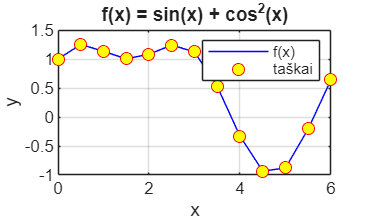

% uzd1
% a)

clear
close all
x = 0:0.5:2*pi;
y = sin(x) + cos(x).^2;

figure(1)
plot(x, y, 'b-')                       % funkcijos linija
hold on
plot(x, y, 'o', 'MarkerEdgeColor', 'r', ...   % kraštai raudoni
     'MarkerFaceColor', 'y')                   % pats taškas geltonas
hold off
title('f(x) = sin(x) + cos^2(x)')
xlabel('x')
ylabel('y')
legend('f(x)', 'taškai')
grid on

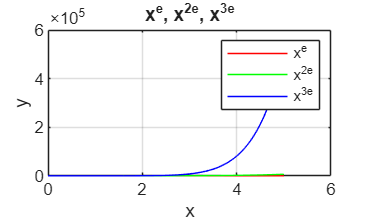


%% b) antras grafinis langas
x = 0:0.01:5;
y1 = x.^exp(1);
y2 = x.^(2*exp(1));
y3 = x.^(3*exp(1));

figure(2)
plot(x, y1, 'r', x, y2, 'g', x, y3, 'b')
title('x^e, x^{2e}, x^{3e}')
xlabel('x')
ylabel('y')
legend('x^e', 'x^{2e}', 'x^{3e}')
grid on

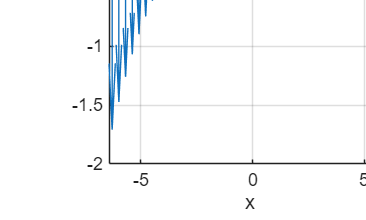

% 2uzd
clear
close all
x = -2*pi:0.3:2*pi;
y = x.^3 + sin(x);

%% a) quiver – vektoriai, išdėstyti horizontalioje linijoje
subplot(1,2,1)
quiver(x, zeros(size(x)), zeros(size(x)), y)
title('y = x.^3 + sin(x) vecotr')
xlabel('x')
ylabel('y')
grid on

%% b) stulpelinė diagrama
subplot(1,2,2)
bar(x, y, 'k')
title('y = x.^3 + sin(x) bar')
xlabel('x')
ylabel('y')
grid on

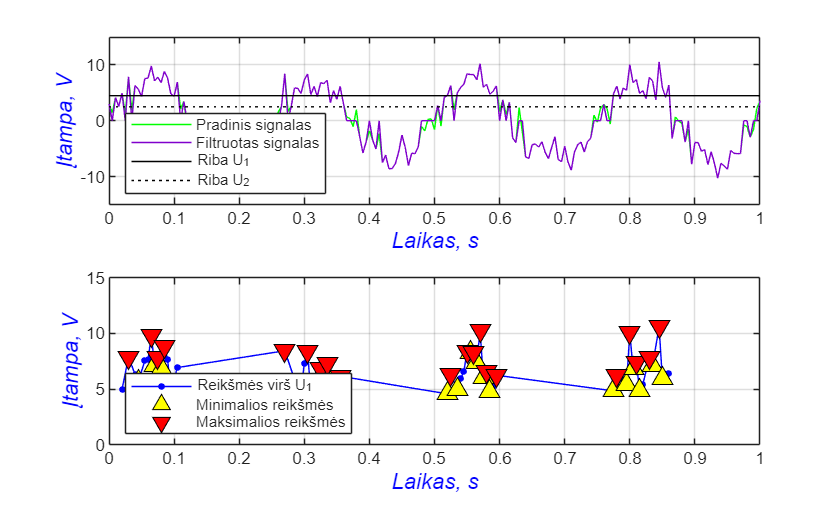

%papildoma
clear
clc
close all

A = 7; f = 4; sigma = 2; U1 = 4.5; U2 = 2.5;

t = 0:0.005:1;
s = A * sin(2*pi*f*t);
n = sigma * randn(size(t));
x = s + n;                       % pradinis signalas

b = x;
b(abs(b) < U2) = 0;              % filtruotas signalas

% reikšmės virš U1
ind = find(x > U1);
tv = t(ind);
xv = x(ind);

% mažiausia ir didžiausia iš jų (pažymimos visos vienodos)
imin = find(xv == min(xv));
imax = find(xv == max(xv));

figure

% a) pirmas grafikas
subplot(2,1,1)
plot(t, x, 'g')
hold on
plot(t, b, 'Color', [0.5 0 0.8])
plot([0 1], [U1 U1], 'k-')
plot([0 1], [U2 U2], 'k:')
hold off
xlabel('Laikas, s', 'Color', 'b', 'FontSize', 11, 'FontAngle', 'italic')
ylabel('Įtampa, V', 'Color', 'b', 'FontSize', 11, 'FontAngle', 'italic')
legend('Pradinis signalas', 'Filtruotas signalas', 'Riba U_1', 'Riba U_2', 'Location', 'southwest')
xlim([0 1])
ylim([-15 15])
grid on

% b) antras grafikas
ind = find(x > U1);
tv = t(ind);
xv = x(ind);

imax = islocalmax(xv);
imin = islocalmin(xv);

subplot(2,1,2)
plot(tv, xv, 'b.-', 'MarkerSize', 10)     % taškai sujungti linija
hold on
plot(tv(imin), xv(imin), '^', 'MarkerFaceColor', 'y', 'MarkerEdgeColor', 'k', 'MarkerSize', 9)
plot(tv(imax), xv(imax), 'v', 'MarkerFaceColor', 'r', 'MarkerEdgeColor', 'k', 'MarkerSize', 9)
hold off
xlabel('Laikas, s', 'Color', 'b', 'FontSize', 11, 'FontAngle', 'italic')
ylabel('Įtampa, V', 'Color', 'b', 'FontSize', 11, 'FontAngle', 'italic')
legend('Reikšmės virš U_1', 'Minimalios reikšmės', 'Maksimalios reikšmės','Location', 'southwest')
xlim([0 1])
ylim([0 15])
grid on